clc, clear all
syms psi q1 q2 q3 q4 q5 l1 l2 l3 l4 l5 a b c ul um un xu yu zu as real
syms rho psi as mu_l mu_m mu_m real

## Simulacion

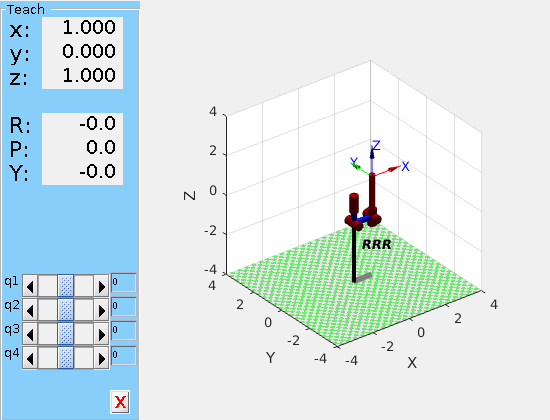

L1 = -1; L2 = 1; L3 = 1; L4 = 1; L5 = 1;
% Primer Brazo
Lx(1) = Link([0 L1 0 -pi/2]); 
Lx(2) = Link([0 0 L2 0 ]);
Lx(3) = Link([0 0 0 pi/2 ]);
Lx(4) = Link([0 L3+L4 0 0]);

robot = SerialLink(Lx);
robot.name = 'RRR';
robot.teach;

## Denavit-Hartembet Modelo Cinematico


H01 = D_H(q1+psi,-l1,0,-pi/2);
H12 = D_H(q2,0,l2,0);
H23 = D_H(q3,0,l3,0);
H34 = D_H(q4,0,0,pi/2);
H45 = D_H(q5,l4+l5,0,0);


H05 = H01*H12*H23*H34*H45;

hx_1 = simplify(H05(1,4))

$$hx\_1 = \cos\left(\psi +q_{1}\right)\,\left(l_{3}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{2}\right)+l_{4}\,\sin\left(q_{2}+q_{3}+q_{4}\right)+l_{5}\,\sin\left(q_{2}+q_{3}+q_{4}\right)\right)$$

hy_1 = simplify(H05(2,4))

$$hy\_1 = \sin\left(\psi +q_{1}\right)\,\left(l_{3}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{2}\right)+l_{4}\,\sin\left(q_{2}+q_{3}+q_{4}\right)+l_{5}\,\sin\left(q_{2}+q_{3}+q_{4}\right)\right)$$

hz_1 = simplify(H05(3,4))

$$hz\_1 = l_{4}\,\cos\left(q_{2}+q_{3}+q_{4}\right)-l_{3}\,\sin\left(q_{2}+q_{3}\right)-l_{2}\,\sin\left(q_{2}\right)-l_{1}+l_{5}\,\cos\left(q_{2}+q_{3}+q_{4}\right)$$


hx = a*cos(psi)- b*sin(psi) + hx_1;
hy = a*sin(psi)+ b*cos(psi) + hy_1;
hz = c + hz_1;
psi = psi;
q5 = q5;


J=jacobian([hx,hy,hz,psi,q5],[mu_l,mu_m,mu_m,psi,q1,q2,q3,q4,q5])

$$J = \begin{array}{l} \left(\begin{array}{ccccccccc} 0 & 0 & 0 & -\sigma_{1}-b\,\cos\left(\psi \right)-a\,\sin\left(\psi \right) & -\sigma_{1} & -\cos\left(\psi +q_{1}\right)\,\sigma_{3} & \cos\left(\psi +q_{1}\right)\,\sigma_{4} & \cos\left(\psi +q_{1}\right)\,\sigma_{5} & 0\\ 0 & 0 & 0 & \sigma_{2}+a\,\cos\left(\psi \right)-b\,\sin\left(\psi \right) & \sigma_{2} & -\sin\left(\psi +q_{1}\right)\,\sigma_{3} & \sin\left(\psi +q_{1}\right)\,\sigma_{4} & \sin\left(\psi +q_{1}\right)\,\sigma_{5} & 0\\ 0 & 0 & 0 & 0 & 0 & -\sigma_{9}-l_{2}\,\cos\left(q_{2}\right)-l_{4}\,\sigma_{10}-l_{5}\,\sigma_{10} & -\sigma_{9}-l_{4}\,\sigma_{10}-l_{5}\,\sigma_{10} & -l_{4}\,\sigma_{10}-l_{5}\,\sigma_{10} & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\psi +q_{1}\right)\,\sigma_{6}\\ \sigma_{2}=\cos\left(\psi +q_{1}\right)\,\sigma_{6}\\ \sigma_{3}=\sigma_{7}+l_{2}\,\sin\left(q_{2}\right)-l_{4}\,\sigma_{8}-l_{5}\,\sigma_{8}\\ \sigma_{4}=l_{4}\,\sigma_{8}-\sigma_{7}+l_{5}\,\sigma_{8}\\ \sigma_{5}=l_{4}\,\sigma_{8}+l_{5}\,\sigma_{8}\\ \sigma_{6}=\sigma_{9}+l_{2}\,\cos\left(q_{2}\right)+l_{4}\,\sigma_{10}+l_{5}\,\sigma_{10}\\ \sigma_{7}=l_{3}\,\sin\left(q_{2}+q_{3}\right)\\ \sigma_{8}=\cos\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{9}=l_{3}\,\cos\left(q_{2}+q_{3}\right)\\ \sigma_{10}=\sin\left(q_{2}+q_{3}+q_{4}\right) \end{array}$$



J(1,1) = cos(psi) ;
J(1,2) = -sin(psi) ;
J(2,1) = sin(psi) ;
J(2,2) = cos(psi) ;
J(3,3) = 1 ;

J=simplify(J)

$$J = \begin{array}{l} \left(\begin{array}{ccccccccc} \cos\left(\psi \right) & -\sin\left(\psi \right) & 0 & -\sigma_{1}-b\,\cos\left(\psi \right)-a\,\sin\left(\psi \right) & -\sigma_{1} & -\cos\left(\psi +q_{1}\right)\,\sigma_{3} & \cos\left(\psi +q_{1}\right)\,\sigma_{4} & \sigma_{6}\,\cos\left(\psi +q_{1}\right)\,\left(l_{4}+l_{5}\right) & 0\\ \sin\left(\psi \right) & \cos\left(\psi \right) & 0 & \sigma_{2}+a\,\cos\left(\psi \right)-b\,\sin\left(\psi \right) & \sigma_{2} & -\sin\left(\psi +q_{1}\right)\,\sigma_{3} & \sin\left(\psi +q_{1}\right)\,\sigma_{4} & \sigma_{6}\,\sin\left(\psi +q_{1}\right)\,\left(l_{4}+l_{5}\right) & 0\\ 0 & 0 & 1 & 0 & 0 & -\sigma_{8}-l_{2}\,\cos\left(q_{2}\right)-l_{4}\,\sigma_{9}-l_{5}\,\sigma_{9} & -\sigma_{8}-l_{4}\,\sigma_{9}-l_{5}\,\sigma_{9} & -\sigma_{9}\,\left(l_{4}+l_{5}\right) & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\psi +q_{1}\right)\,\sigma_{5}\\ \sigma_{2}=\cos\left(\psi +q_{1}\right)\,\sigma_{5}\\ \sigma_{3}=\sigma_{7}+l_{2}\,\sin\left(q_{2}\right)-l_{4}\,\sigma_{6}-l_{5}\,\sigma_{6}\\ \sigma_{4}=l_{4}\,\sigma_{6}-\sigma_{7}+l_{5}\,\sigma_{6}\\ \sigma_{5}=\sigma_{8}+l_{2}\,\cos\left(q_{2}\right)+l_{4}\,\sigma_{9}+l_{5}\,\sigma_{9}\\ \sigma_{6}=\cos\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{7}=l_{3}\,\sin\left(q_{2}+q_{3}\right)\\ \sigma_{8}=l_{3}\,\cos\left(q_{2}+q_{3}\right)\\ \sigma_{9}=\sin\left(q_{2}+q_{3}+q_{4}\right) \end{array}$$

## +UAV